% File path for the CSV file
filepath = "C:\Users\dhiid\OneDrive\Desktop\Matlab simulations\tracking_data.csv";

% Read the CSV file into a table
data = readtable(filepath);

% Display the first few rows to check the structure
disp(data(1:5, :));

     Var1      Var2    Var3    Var4    Var5
    _______    ____    ____    ____    ____

    0.27829    2.19    7.19    1.55    7.15
    0.29755    2.19    7.19    1.55    7.15
    0.31377    2.19    7.19    1.55    7.15
    0.34902    2.19    7.19    1.55    7.15
    0.37254    2.19    7.19    1.55    7.15



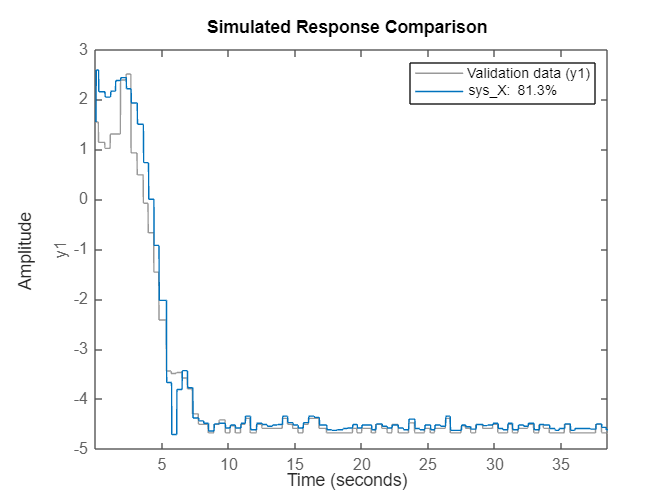

 
% Extract relevant columns for system input and output 
t = data{2,1}-data{1,1};
x1 = data{:, 2};  % Actual system output (e.g., measured x1)
y1 = data{:, 3};  % Actual system output (e.g., measured y1, if needed)
x2 = data{:, 4};  % Desired setpoint (input)
y2 = data{:, 5};  % Desired setpoint (target y2, if needed) 


% Define PID controller parameters (example values)
Kp = 20;   % Proportional gain
Ki = 0;    % Integral gain
Kd = 0;    % Derivative gain

% PID controller transfer function
C_pid = pid(Kp, Ki, Kd);

% Define the number of samples (assume a unit time step)
numSamples = length(x1);  % The length of the data set

% Create input-output data for system identification
% Here, we assume that x1 is the output and x2 is the input

% X-axis system identification
sysData_X = iddata(x2, x1, t);
sys_X = tfest(sysData_X, 1);

% Y-axis system identification
sysData_Y = iddata(y2, y1, t);
sys_Y = tfest(sysData_Y, 1,1);

% sys_comp = sys * C_pid;  % Combine the plant with the lead compensator  

compare(sysData_X,sys_X);

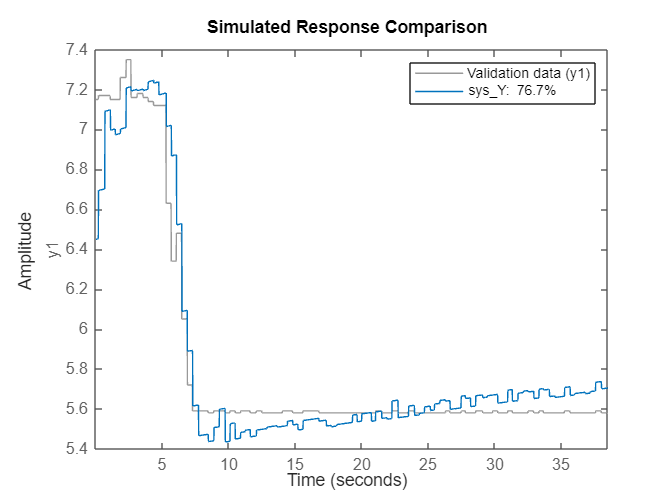

compare(sysData_Y,sys_Y);

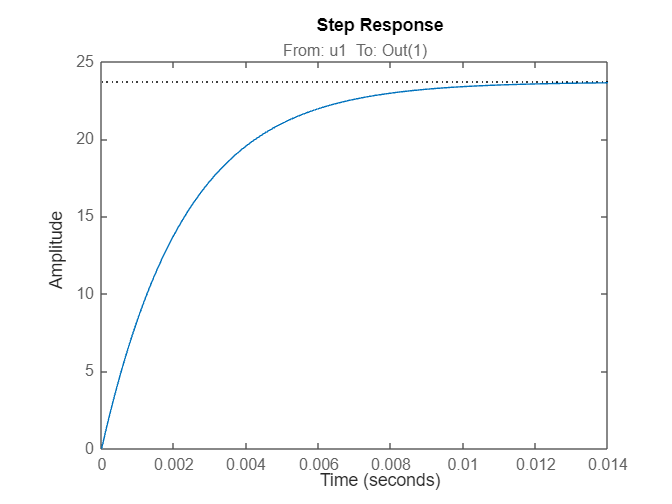


K = C_pid;
Gx = K * sys_X; 
Gy = K*sys_Y;

% bode(closedLoopSystem);

step(Gx); 

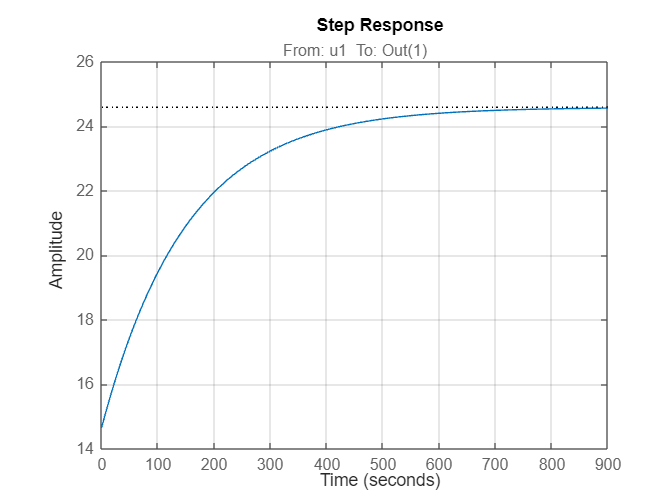

step(Gy);
grid on;   

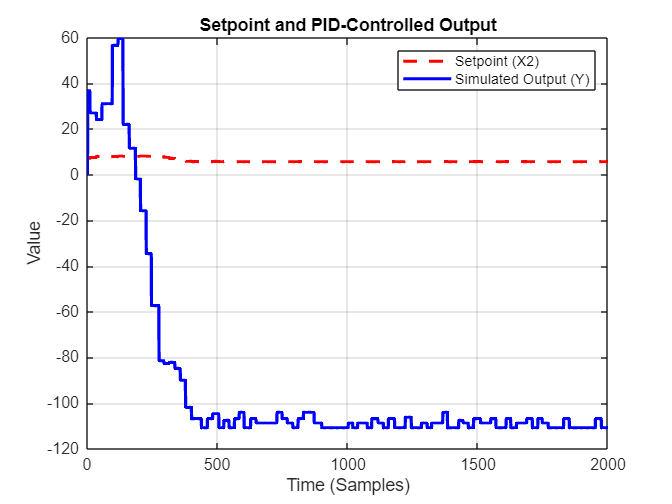

stepinfo(Gx);
stepinfo(Gy);


% Simulate the system response over time
% [y_sim, t_sim] = lsim(Gx, x2, time);
% 
% % Save the simulation results to a new CSV file
% simResults = table(t_sim, y_sim);
% writetable(simResults, 'tuned_pid_simulation_results.csv');
% 
% % % Plot the results: compare the setpoint (x2) and the simulated output (y_sim)
% figure;
% plot(t_sim, inputData, '--r', 'LineWidth', 2, 'DisplayName', 'Setpoint (X2)');
% hold on;
% plot(t_sim, y_sim, '-b', 'LineWidth', 2, 'DisplayName', 'Simulated Output (Y)');
% xlabel('Time (Samples)');
% ylabel('Value');
% title('Setpoint and PID-Controlled Output');
% legend;
% grid on;
% hold off;